Decision trees are a fundamental machine learning technique. To implement a decision tree in MATLAB, you'll need to follow these steps:

- Understand the Concept: A decision tree is a model used for both classification and regression. It divides the data into subsets based on feature value conditions, represented as branches of the tree.

- Prepare Your Data: For a simple example, you could use MATLAB's built-in datasets like the Fisher Iris dataset.

- Use MATLAB's Tools: MATLAB has a Machine Learning Toolbox that includes functions and apps for creating, analyzing, and tuning decision trees.

Here's a step-by-step guide to creating a basic decision tree in MATLAB:

**Step 1: Load and Prepare Data**

% Load the Fisher Iris dataset
load fisheriris;
% The dataset includes 150 observations for iris flowers and 4 features: sepal length, sepal width, petal length, and petal width.
% 'species' contains the class labels

**Step 2: Create the Decision Tree**

% Create a decision tree for classification
tree = fitctree(meas, species);

**Step 3: View the Tree**

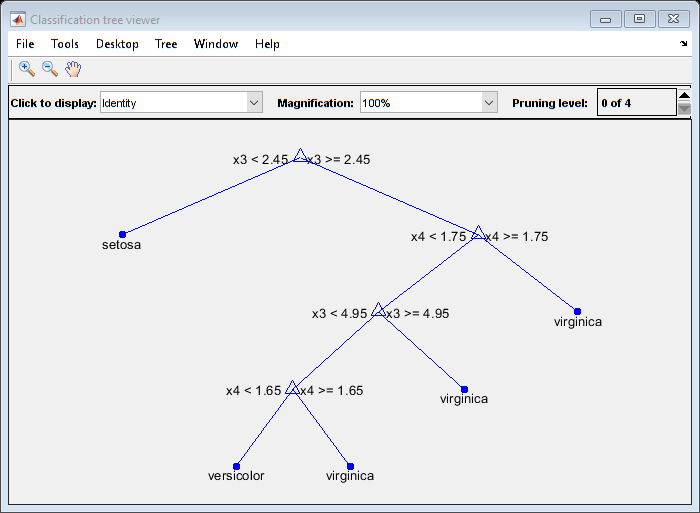

% View the tree
view(tree, 'Mode', 'graph');

**Step 4: Predict New Data**

% Suppose you have new measurements
newData = [5.1, 3.5, 1.4, 0.2];
% Predict the species of the new data
predictedSpecies = predict(tree, newData);
disp(['The predicted species is: ', predictedSpecies{1}]);

The predicted species is: setosa


**Step 5: Evaluate the Tree**

% Split data into training and test sets
cv = cvpartition(size(meas, 1), 'HoldOut', 0.2);
idx = cv.test;
% Separate to training and testing sets
trainData = meas(~idx,:);
trainLabels = species(~idx);
testData = meas(idx,:);
testLabels = species(idx);

% Train the model
trainedTree = fitctree(trainData, trainLabels);

% Predict for test data
testPredictions = predict(trainedTree, testData);

% Calculate the accuracy
accuracy = sum(strcmp(testPredictions, testLabels)) / numel(testLabels);
disp(['Accuracy of the decision tree: ', num2str(accuracy * 100), '%']);

Accuracy of the decision tree: 93.3333%
